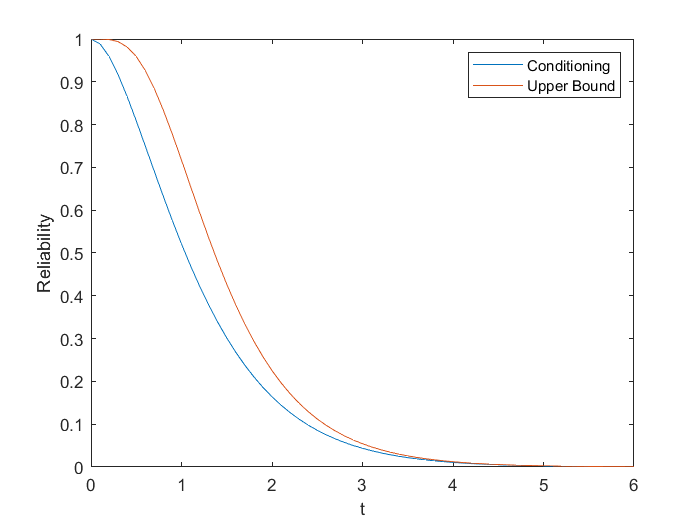

% Grafico 1 es 1
t = (0:0.1:6);
lambda = 0.5;
Rsys=exp(-5*lambda*t)-5*exp(-4*lambda*t)+5*exp(-3*lambda*t);
Rub = 1-(1-exp(-3*lambda*t)).^5;
plot(t,Rsys, t, Rub)
legend('Conditioning', 'Upper Bound')
xlabel('t')
ylabel('Reliability')

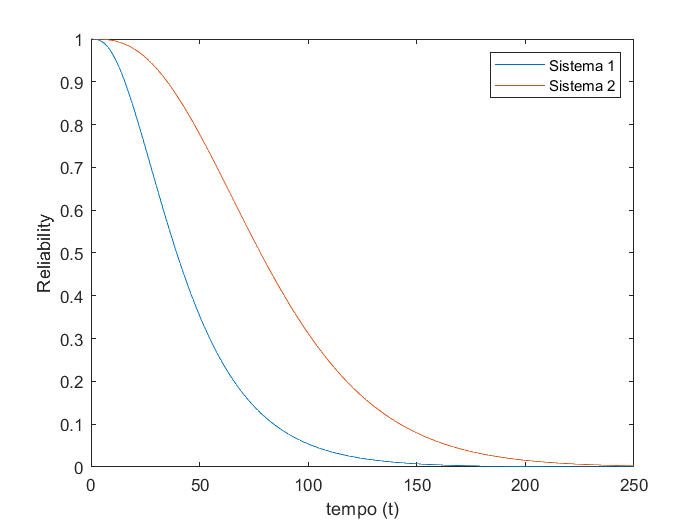

% Grafico 2 es 1
%r=(0:0.01:1);
t1 = (0:1:250);
r=exp(-t1/100);
R1 = 1-(1-r.^4).^3;
R2 = (1-(1-r).^3).^4;
plot(t1,R1,t1,R2)
legend('Sistema 1', 'Sistema 2')
xlabel('tempo (t)')
ylabel('Reliability')

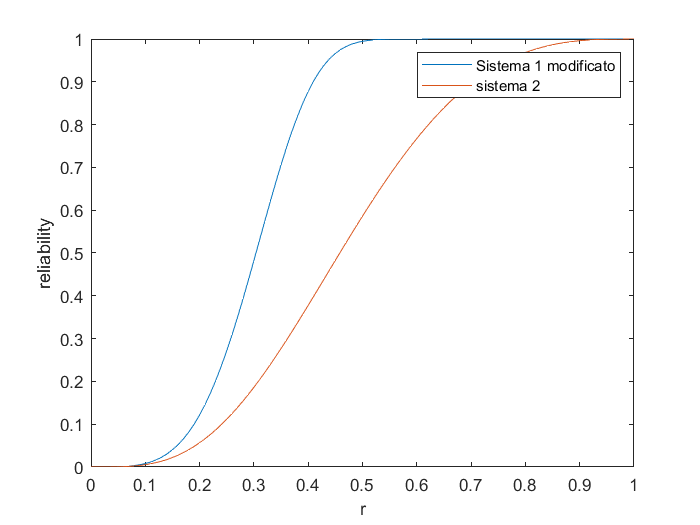

% Grafico 1 es 2
rnew= (0:0.01:1);
R1mod= 1-(1-rnew.^4).^(3^4);
R2p= (1-(1-rnew).^3).^4;
plot(rnew,R1mod,rnew,R2p)
legend('Sistema 1 modificato', 'sistema 2')
ylabel('reliability')
xlabel('r')

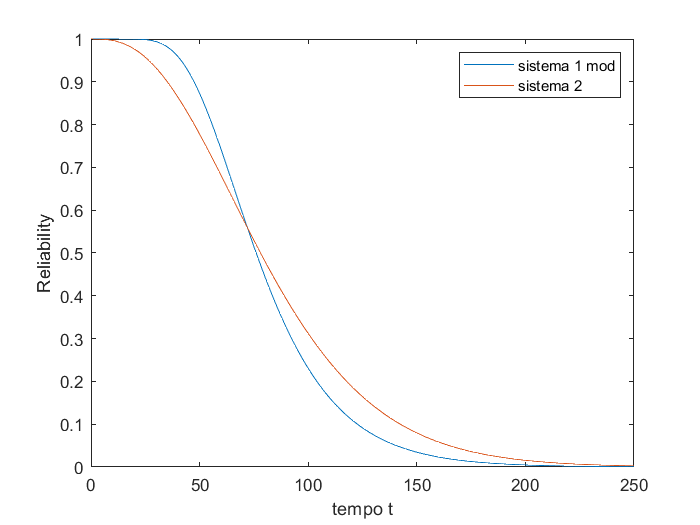

% Grafico 2 es 2

r_calc = exp(-72/100);
n = log(1-(1-(1-r_calc).^3).^4)/log(1-r_calc.^4);

R1modt= 1-(1-r.^4).^(n);
plot(t1,R1modt,t1,R2)
legend("sistema 1 mod", "sistema 2")
ylabel('Reliability')
xlabel('tempo t')

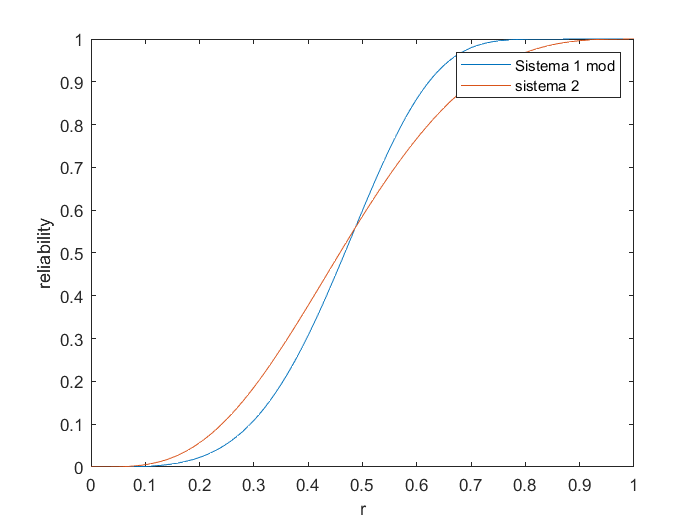

% Grafico 3 es 2 (al variare di r)
rnew= (0:0.01:1);
R1mod= 1-(1-rnew.^4).^(n);
R2p= (1-(1-rnew).^3).^4;
plot(rnew,R1mod,rnew,R2p)
legend('Sistema 1 mod', 'sistema 2')
ylabel('reliability')
xlabel('r')

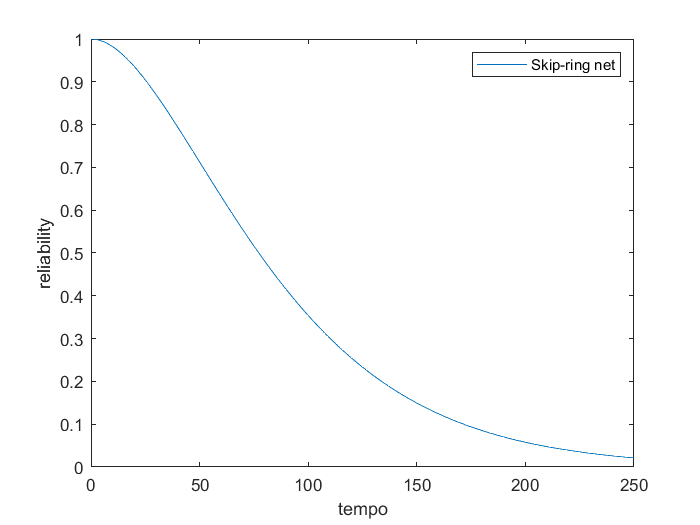

% Grafico 1 es 3

R_m=exp(-0.005*t1);
R_sys=R_m.^8 + 8*R_m.^7.*(1-R_m) +20*R_m.^6.*(1-R_m).^2 + 16*R_m.^5.*(1-R_m).^3 +2*R_m.^4.*(1-R_m).^4;

plot(t1,R_sys);
legend('Skip-ring net')

ylabel('reliability')
xlabel('tempo')

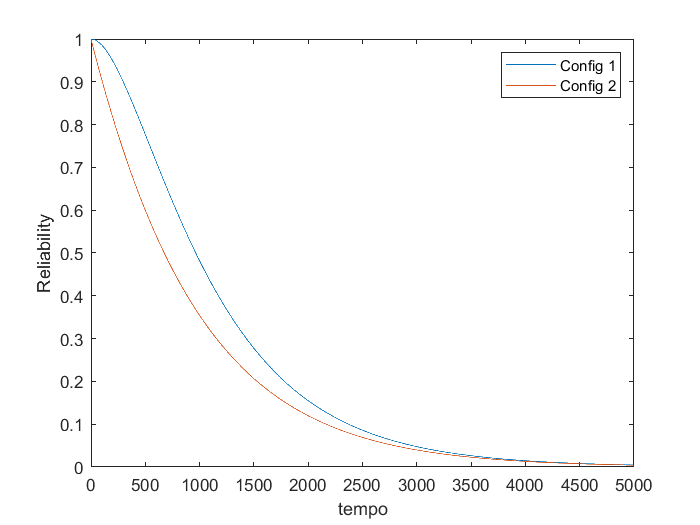

% Grafico 1 es 4

t=(0:1:5000);

R_1_1 = -exp(-0.0026*t)+exp(-0.0011*t)+exp(-0.0015*t);
R_2_1 = -exp(-0.0016*t)+exp(-0.0011*t)+exp(-0.0015*t);

plot(t,R_1_1, t,R_2_1)
legend('Config 1', 'Config 2')

ylabel('Reliability')
xlabel('tempo')

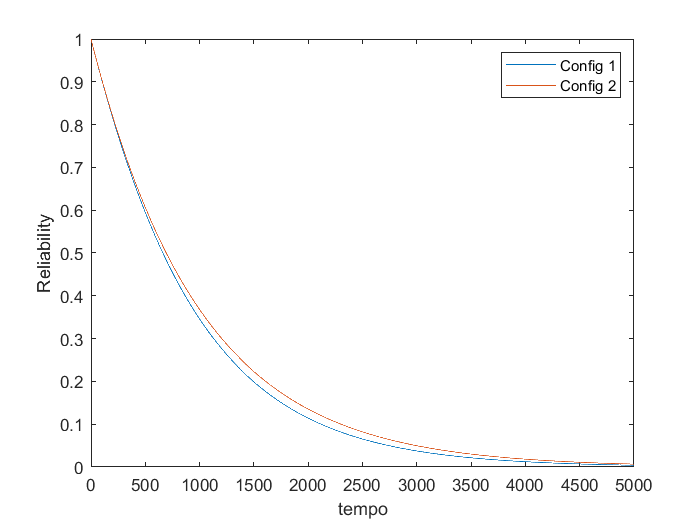

% Grafico 2 es 4
R_1_2 = -exp(-0.0021*t)+exp(-0.0011*t)+exp(-0.002*t);
R_2_2 = exp(-0.001*t);

plot(t,R_1_2, t,R_2_2)
legend('Config 1', 'Config 2')

ylabel('Reliability')
xlabel('tempo')

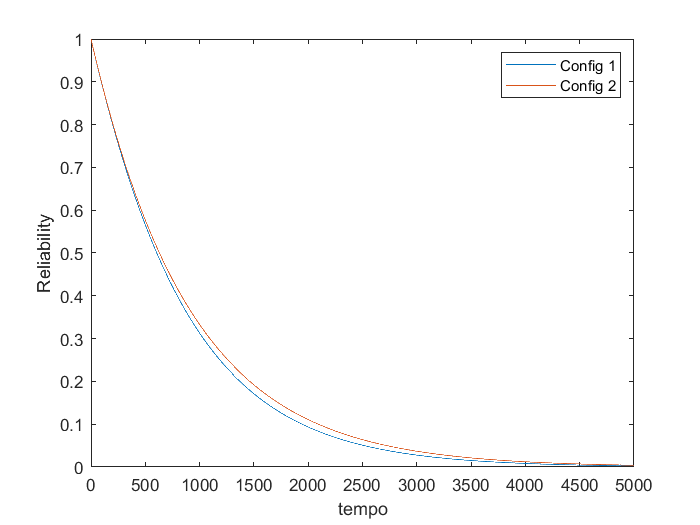

% Grafico 3 es 4
R_1_3 = -exp(-0.0022*t)+exp(-0.0021*t)+exp(-0.0012*t);
R_2_3 = exp(-0.0011*t);

plot(t,R_1_3, t,R_2_3)
legend('Config 1', 'Config 2')

ylabel('Reliability')
xlabel('tempo')

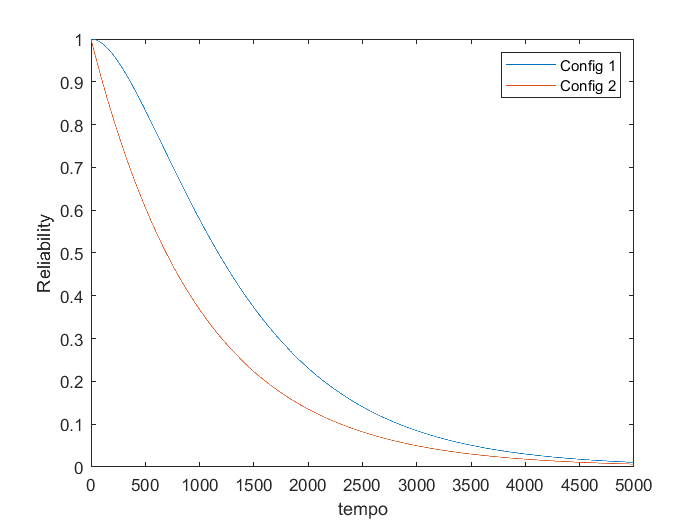

% Grafico 4 es 4
R_1_4 = -exp(-0.0021*t)+exp(-0.0011*t)+exp(-0.001*t);
R_2_4 = exp(-0.001*t);

plot(t,R_1_4, t,R_2_4)
legend('Config 1', 'Config 2')

ylabel('Reliability')
xlabel('tempo')

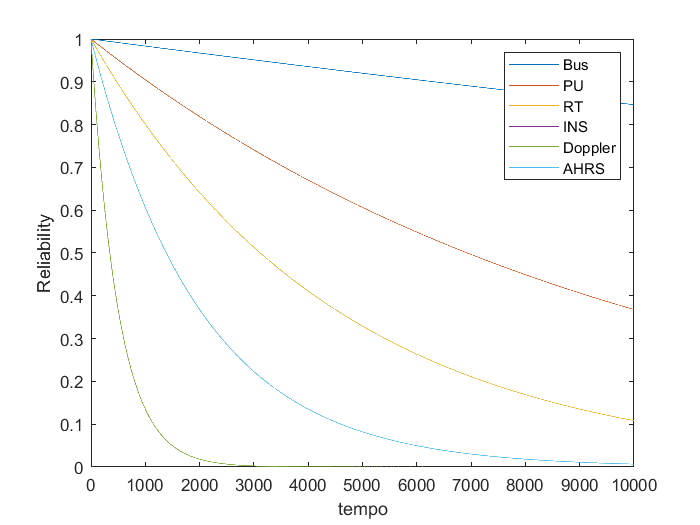

% Grafico 1 es 5 (comp rel tra sottosistemi)
t=(0:1:10000);

R_bus= exp(-t/60000);
R_pu=exp(-t/10000);
R_rt=exp(-t/4500);
R_ins=exp(-t/2000);
R_dop=exp(-t/500);
R_ahrs=exp(-t/2000);
R_elic = (1-(1-R_bus).^2).*(1-(1-R_bus).^2).*(1-(1-R_pu).^2).*(1-(1-R_rt).^2).*(1-(1-R_ins).*(1-R_dop)).*(1-(1-R_ins).*(1-R_ahrs).^3);

plot(t, R_bus, t,R_pu, t,R_rt, t,R_ins, t,R_dop, t,R_ahrs)
legend('Bus','PU', 'RT', 'INS', 'Doppler', 'AHRS')
ylabel('Reliability')
xlabel('tempo')

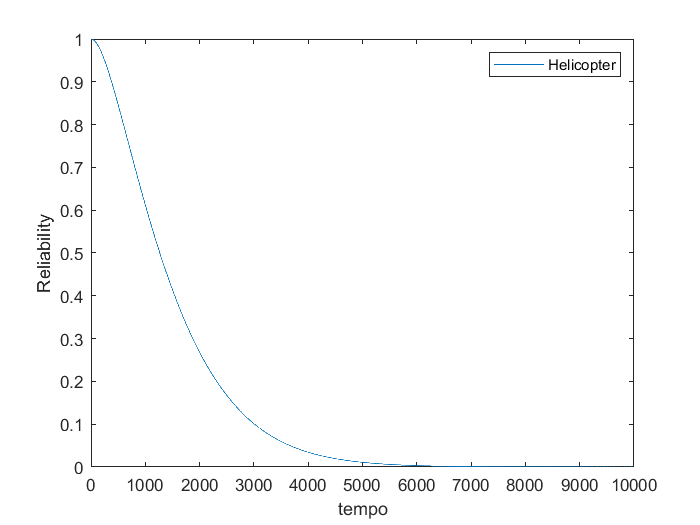

% grafico 2 es 5 (rel sistema elicottero)
plot(t,R_elic)
legend('Helicopter')

ylabel('Reliability')
xlabel('tempo')

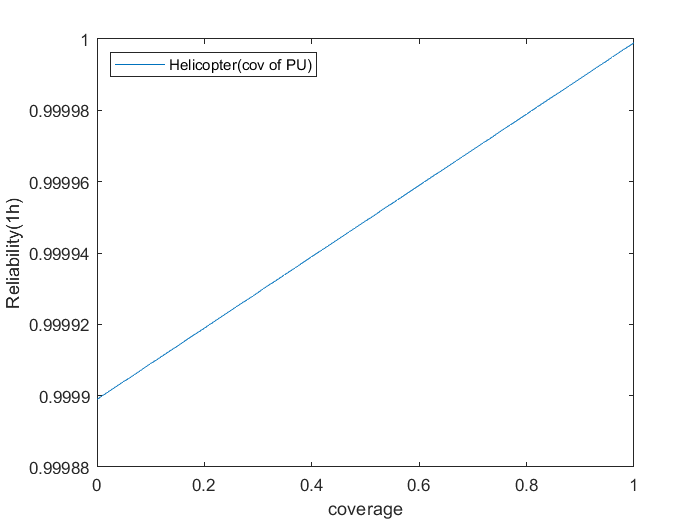

%grafico 3 es 5 (rel al variare di coverage)
c=(0:0.01:1);
R_bus_1= exp(-1/60000);
R_pu_1=exp(-1/10000);
R_rt_1=exp(-1/4500);
R_ins_1=exp(-1/2000);
R_dop_1=exp(-1/500);
R_ahrs_1=exp(-1/2000);
R_elic_1 = (1-(1-R_bus_1).^2).*(1-(1-R_bus_1).^2).*(R_pu_1 +c.*(1-R_pu_1).*R_pu_1).*(1-(1-R_rt_1).^2).*(1-(1-R_ins_1).*(1-R_dop_1)).*(1-(1-R_ins_1).*(1-R_ahrs_1).^3);

plot (c, R_elic_1)
legend('Helicopter(cov of PU)', location="NW")

ylabel('Reliability(1h)')
xlabel('coverage')